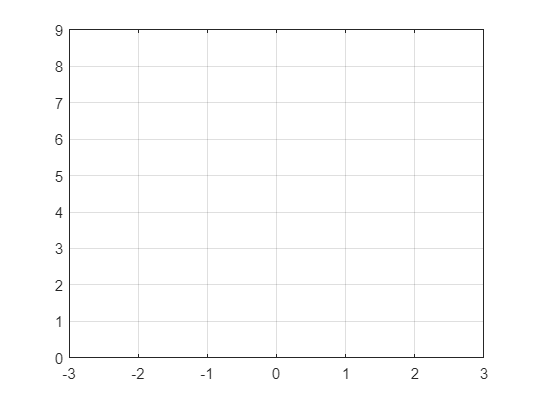

clear
t = linspace(-3,3,100);
y1 = exp(-t.*t);
y2 = 3*exp(1) * exp(-t.*t);
plot(t,y1)
grid on
hold on
plot(t, y2)

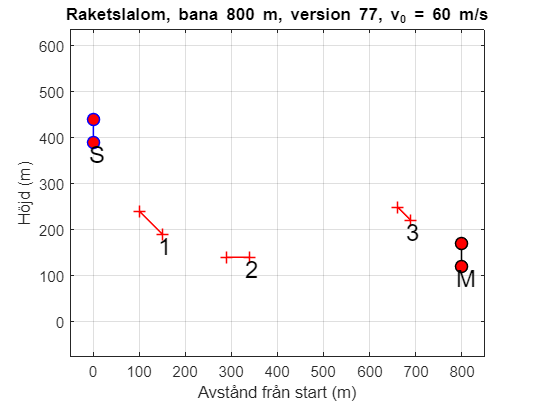

clear
load bana800-77.mat
plotTrack(portx, porty, ver, v1)

c = 0.25;
g = 9.82;
km = 2000;
alpha = 0;
m1 = 40;

t = linspace(0, 800, 100);

t =          0    8.0808   16.1616   24.2424   32.3232   40.4040   48.4848   56.5657   64.6465   72.7273   80.8081   88.8889   96.9697  105.0505  113.1313  121.2121  129.2929  137.3737  145.4545  153.5354  161.6162  169.6970  177.7778  185.8586  193.9394  202.0202  210.1010  218.1818  226.2626  234.3434  242.4242  250.5051  258.5859  266.6667  274.7475  282.8283  290.9091  298.9899  307.0707  315.1515  323.2323  331.3131  339.3939  347.4747  355.5556  363.6364  371.7172  379.7980  387.8788  395.9596


y = 400 - t/3

y =   400.0000  397.3064  394.6128  391.9192  389.2256  386.5320  383.8384  381.1448  378.4512  375.7576  373.0640  370.3704  367.6768  364.9832  362.2896  359.5960  356.9024  354.2088  351.5152  348.8215  346.1279  343.4343  340.7407  338.0471  335.3535  332.6599  329.9663  327.2727  324.5791  321.8855  319.1919  316.4983  313.8047  311.1111  308.4175  305.7239  303.0303  300.3367  297.6431  294.9495  292.2559  289.5623  286.8687  284.1751  281.4815  278.7879  276.0943  273.4007  270.7071  268.0135


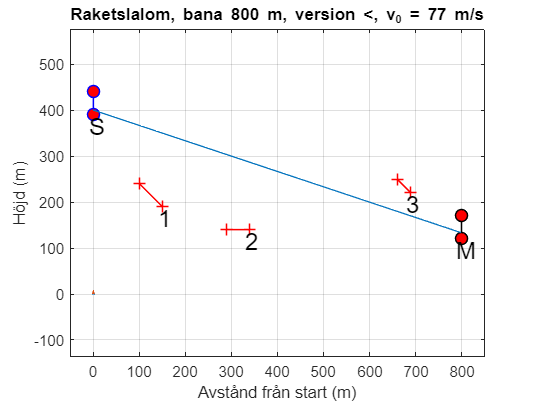

hold on
plot(t,y)

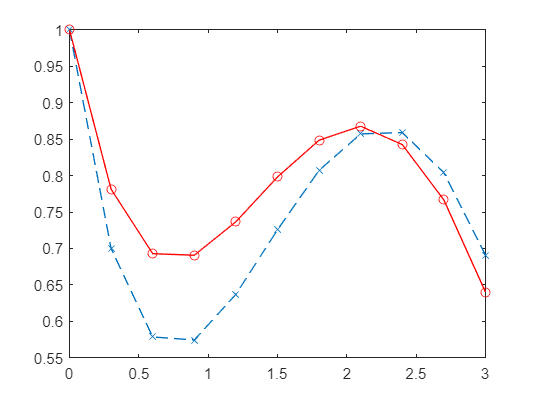

hold off

clear
tspan = [0,3];
n = 100;
y1 = 1;
[t, y] = minEuler(@funkEx1, tspan, y1, n);
plot(t, y, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;

ye =     1.0000    0.9709    0.9435    0.9179    0.8938    0.8714    0.8505    0.8311    0.8131    0.7965    0.7813    0.7674    0.7547    0.7432    0.7329    0.7237    0.7156    0.7085    0.7023    0.6972    0.6929    0.6894    0.6868    0.6850    0.6839    0.6835    0.6838    0.6847    0.6862    0.6882    0.6907    0.6937    0.6972    0.7010    0.7053    0.7098    0.7147    0.7199    0.7252    0.7308    0.7366    0.7426    0.7486    0.7548    0.7610    0.7672    0.7735    0.7797    0.7859    0.7920


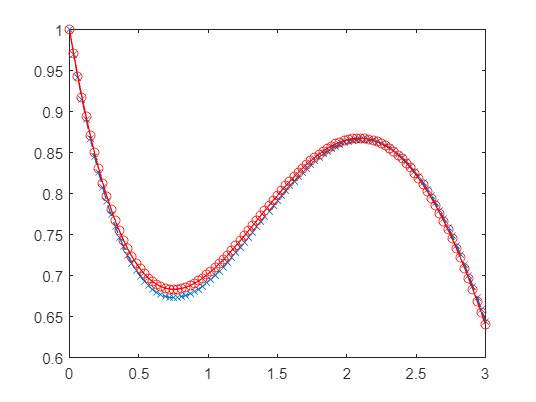

hold on
plot(t, ye, 'r-o')

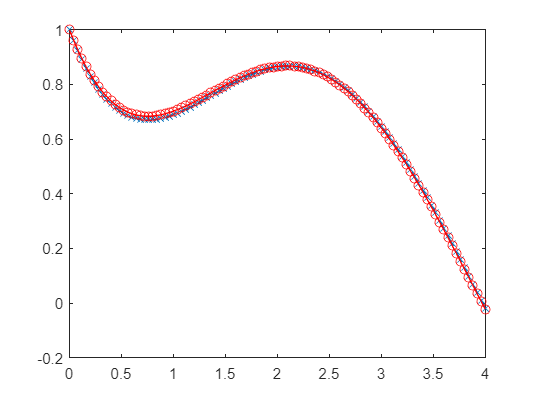

clear
hold off

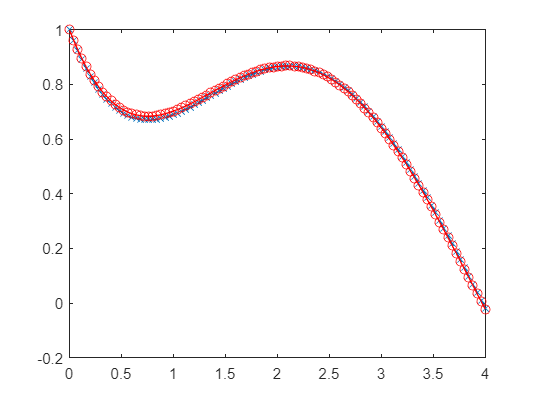

tspan = [0,4];
n = 100;
y1 = 1;
[~, y] = minEuler(@funkEx2, tspan, y1, n);
[t, y2] = minRK2(@funkEx2, tspan, y1, n);
plot(t, y, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;
hold on
plot(t, y2, 'r-o')